# Guía 3 - Ejercicio 1

## Enunciado

Hacer una red de Kohonen de 2 entradas que aprenda una distribución uniforme dentro del círculo unitario. Mostrar el mapa de preservación de topología. Probar con distribuciones uniformes dentro de otras figuras geométricas.

Creo los N patrones

clear all
N=20;
patrones = zeros([2 N]);

Patron cuadrado

for i=1:N
    patrones(:,i) = rand([2 1]);
end

Muestro la distribución de patrones

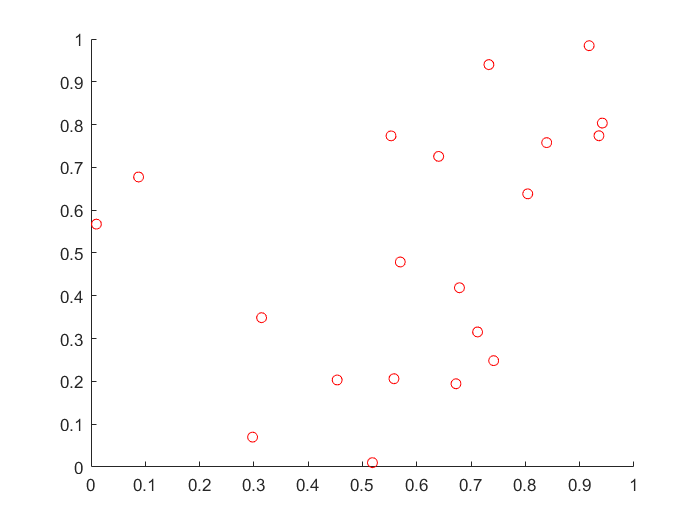

figure()
hold on
scatter(patrones(1,:), patrones(2,:), 'red')
axis([0 1 0 1])

Creo la matriz de pesos sinápticos

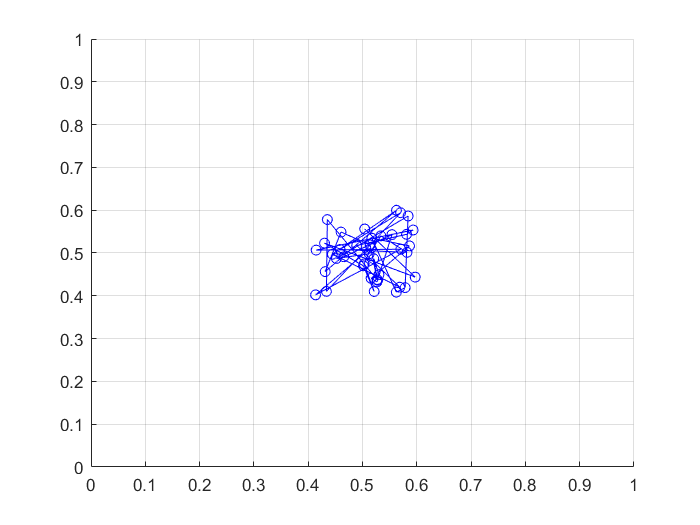

T = 2*N;
matriz = rand([2 T]);
matriz = matriz/5+[0.4;0.4];


figure()
hold on
for j=1:T
    scatter(matriz(1,:), matriz(2,:),'blue')
    plot(matriz(1,:), matriz(2,:),'blue')
end
grid on
axis([0 1 0 1])

Entreno grueso

sigma = T/10;
eta = 0.05;

for epoch=1:500
    orden = randperm(length(patrones));
    for k = 1:length(patrones)
        mascara = zeros([2 T]);
        %elijo un vector
        elegido = patrones(:,orden(k));
        %busco al mayor de las neuronas y obtengo la posición en espacio neurona
        matriz_elegido = ones([2 T]).*elegido;
        diferencia = matriz_elegido-matriz;
        norma = (diferencia(1,:).^2+diferencia(2,:).^2).^(1/2);
        [valor,posicion] = min(norma(:));
        %creo la matriz de pesos de update
        for l = 0:T/2
            if (l+posicion<=T)
                mascara(:,posicion+l) = exp(-((l)^2)/(2*sigma^2));
            else
                mascara(:,posicion+l-T) = exp(-((l)^2)/(2*sigma^2));
            end
        end
        for l = 0:-1:-T/2
            if (l+posicion>0)
                mascara(:,posicion+l) = exp(-((l)^2)/(2*sigma^2));
            else
                mascara(:,T+posicion+l) = exp(-((l)^2)/(2*sigma^2));
            end
        end
        delta = eta*(diferencia).*mascara;
        matriz = matriz+ delta;

    end
    if sigma>T/100
        sigma = sigma*0.995;
    end
    %eta = eta*0.995;
end

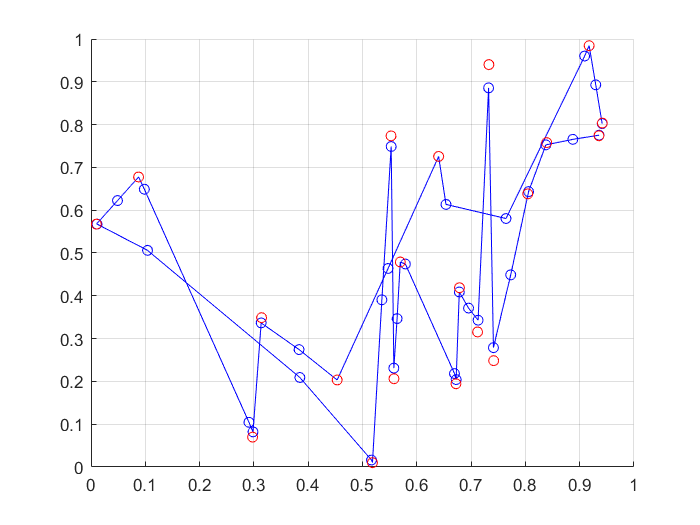

figure()
hold on
for j=1:T
    scatter(matriz(1,:), matriz(2,:),'blue')
    plot(matriz(1,:), matriz(2,:),'blue')
end
scatter(patrones(1,:), patrones(2,:), 'red')
grid on
axis([0 1 0 1])